% --- Template for Plotting FinalProcessedSpectrum from dataTable_allpositions by Diss_ID List ---

% --- User Inputs ---
% Specify the Diss_IDs you want to plot spectra for.
% This should be a cell array of strings.
diss_ids_to_plot = {'MEN-080-01'}; % <<< CHANGE THIS LIST

% Names of the table and relevant columns (as strings)
table_name_str = 'dataTable_allpositions';
spectra_col_name_str = 'FinalProcessedSpectrum';
diss_id_col_name_str = 'Diss_ID'; % Assuming this is the column name for Diss_ID

% --- Configuration for Plotting ---
use_master_prompt_ylim = false; % Use fixed Y-limits from master prompt
master_prompt_ylim = [0 1.0];
master_prompt_yticks = 0:0.2:1.0;
master_prompt_xlim = [950 1800];
master_prompt_fontsize = 12;

% Filename prefix for any saved items (though this script primarily plots)
% Current date: Wednesday, May 14, 2025
datePrefix = '20250514'; 

disp('--- Plotting Template for dataTable_allpositions.FinalProcessedSpectrum Initialized ---');

--- Plotting Template for dataTable_allpositions.FinalProcessedSpectrum Initialized ---



% --- Validate presence of necessary variables in workspace ---
if ~evalin('base', sprintf('exist(''%s'', ''var'')', table_name_str))
    error('Table ''%s'' not found in the base workspace. Please load it.', table_name_str);
end
dataTable = evalin('base', table_name_str); % Get the table from workspace

if ~evalin('base', "exist('wavenumbers_roi', 'var')")
    error('Variable ''wavenumbers_roi'' not found in the base workspace. Please load it.');
end
wavenumbers_roi = evalin('base', 'wavenumbers_roi');

% --- Validate table structure ---
if ~istable(dataTable)
    error('''%s'' is not a valid MATLAB table.', table_name_str);
end
if ~ismember(spectra_col_name_str, dataTable.Properties.VariableNames)
    error('Table ''%s'' does not have the specified spectra column: ''%s''.', table_name_str, spectra_col_name_str);
end
if ~ismember(diss_id_col_name_str, dataTable.Properties.VariableNames)
    error('Table ''%s'' does not have the specified Diss_ID column: ''%s''.', table_name_str, diss_id_col_name_str);
end
if isempty(diss_ids_to_plot)
    disp('The "diss_ids_to_plot" cell array is empty. Nothing to plot.');
    return;
end
if ~iscellstr(diss_ids_to_plot) && ~isstring(diss_ids_to_plot) %#ok<ISCLSTR>
    error('"diss_ids_to_plot" must be a cell array of strings or a string array.');
end

disp(['Targeting table: ''' table_name_str ''', Spectra column: ''' spectra_col_name_str '''.']);

Targeting table: 'dataTable_allpositions', Spectra column: 'FinalProcessedSpectrum'.



Searching for Diss_ID: MEN-080-01


Found 3 entr(y/ies) for Diss_ID: MEN-080-01. Plotting each...


  Plotting spectra for: Diss_ID: MEN-080-01 (Zeile 130), Position: Pos1


    Enthält 256 Einzelspektrum/-spektren.


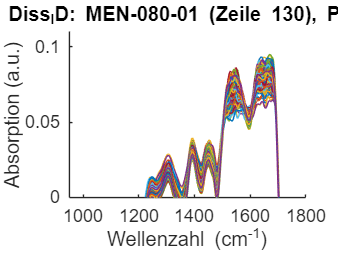

        Plotting 256 Spektren. Legende zur Übersichtlichkeit weggelassen.


    Plot erfolgreich erstellt für: Diss_ID: MEN-080-01 (Zeile 130), Position: Pos1


  Plotting spectra for: Diss_ID: MEN-080-01 (Zeile 131), Position: Pos2


    Enthält 256 Einzelspektrum/-spektren.


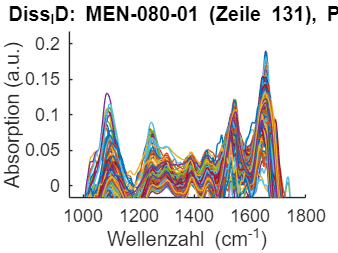

        Plotting 256 Spektren. Legende zur Übersichtlichkeit weggelassen.


    Plot erfolgreich erstellt für: Diss_ID: MEN-080-01 (Zeile 131), Position: Pos2


  Plotting spectra for: Diss_ID: MEN-080-01 (Zeile 132), Position: Pos3


    Enthält 256 Einzelspektrum/-spektren.


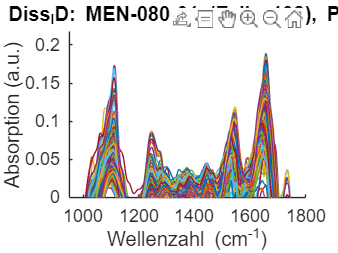

        Plotting 256 Spektren. Legende zur Übersichtlichkeit weggelassen.


    Plot erfolgreich erstellt für: Diss_ID: MEN-080-01 (Zeile 132), Position: Pos3



% --- Loop through each specified Diss_ID ---
for id_idx = 1:length(diss_ids_to_plot)
    target_diss_id = diss_ids_to_plot{id_idx};
    
    fprintf('\nSearching for Diss_ID: %s\n', target_diss_id);
    
    % Find all rows in the table that match the current target_diss_id
    % Assuming Diss_ID column contains cellstrs or strings
    if iscellstr(dataTable.(diss_id_col_name_str)) || isstring(dataTable.(diss_id_col_name_str))
        matching_row_indices = find(strcmpi(dataTable.(diss_id_col_name_str), target_diss_id));
    else
        warning('Diss_ID column ''%s'' is not cell array of strings or string array. Cannot perform string comparison for Diss_ID: %s. Skipping.', diss_id_col_name_str, target_diss_id);
        continue;
    end
    
    if isempty(matching_row_indices)
        warning('No rows found in ''%s'' for Diss_ID: %s.', table_name_str, target_diss_id);
        continue;
    end
    
    fprintf('Found %d entr(y/ies) for Diss_ID: %s. Plotting each...\n', length(matching_row_indices), target_diss_id);
    
    % --- Loop through each matching row for the current Diss_ID ---
    for k_match = 1:length(matching_row_indices)
        rowIndex = matching_row_indices(k_match);
        
        identifier_string_for_title = sprintf('Diss_ID: %s (Zeile %d)', target_diss_id, rowIndex); % German: Row
        
        % Attempt to add other relevant identifiers if they exist
        potential_extra_id_cols = {'Position', 'Spot_ID', 'ProbeUID'}; % Example other ID columns
        for ex_id_col_idx = 1:length(potential_extra_id_cols)
            current_ex_id_col = potential_extra_id_cols{ex_id_col_idx};
            if ismember(current_ex_id_col, dataTable.Properties.VariableNames)
                ex_id_value = dataTable.(current_ex_id_col)(rowIndex);
                 if iscell(ex_id_value) && ~isempty(ex_id_value); ex_id_value_str = ex_id_value{1};
                 elseif isstring(ex_id_value) || ischar(ex_id_value); ex_id_value_str = char(ex_id_value);
                 elseif isnumeric(ex_id_value); ex_id_value_str = num2str(ex_id_value);
                 else; ex_id_value_str = ''; end
                 if ~isempty(ex_id_value_str)
                    identifier_string_for_title = [identifier_string_for_title ', ' current_ex_id_col ': ' ex_id_value_str]; %#ok<AGROW>
                 end
            end
        end

        fprintf('  Plotting spectra for: %s\n', identifier_string_for_title);
        
        % Extract spectra matrix from the specified column for the current row
        % Assumes it's an N x W matrix (Spectra x Wavenumbers)
        spectra_to_plot = dataTable.(spectra_col_name_str){rowIndex};
        
        % --- Validate extracted spectra ---
        if isempty(spectra_to_plot)
            disp(['    Keine Spektren in ''' spectra_col_name_str ''' für ' identifier_string_for_title ' gefunden.']); % German: No spectra found
            continue; 
        end
        if ~isnumeric(spectra_to_plot) || ndims(spectra_to_plot) ~= 2
            warning(['    ''' spectra_col_name_str ''' für ' identifier_string_for_title ' ist keine 2D numerische Matrix. Wird übersprungen.']); % German: is not a 2D numeric matrix. Skipping.
            continue;
        end
        if size(spectra_to_plot,1) == 0
            disp(['    ''' spectra_col_name_str ''' für ' identifier_string_for_title ' enthält keine Spektren (0 Zeilen).']); % German: contains no spectra (0 rows)
            continue;
        end
        if size(spectra_to_plot, 2) ~= length(wavenumbers_roi)
            warning(['    Anzahl der Wellenzahlen für ' identifier_string_for_title ' stimmt nicht überein. ' ... % German: Mismatch
                     'Erwartet: %d, Gefunden: %d. Plot wird übersprungen.'], length(wavenumbers_roi), size(spectra_to_plot, 2));
            continue;
        end
        
        num_spectra_in_cell = size(spectra_to_plot, 1);
        disp(['    Enthält ' num2str(num_spectra_in_cell) ' Einzelspektrum/-spektren.']); % German: Contains X individual spectrum/spectra

        % --- Plotting for the current row/entry ---
        figure('Name', ['Spektren: ' identifier_string_for_title]);
        hold on;
        for i_spec = 1:num_spectra_in_cell
            plot(wavenumbers_roi, spectra_to_plot(i_spec, :));
        end
        hold off;
        
        % --- Formatting (Adhering to Master Prompt Guidelines) ---
        xlabel('Wellenzahl (cm^{-1})', 'FontSize', master_prompt_fontsize); % German
        ylabel('Absorption (a.u.)', 'FontSize', master_prompt_fontsize);    % German
        
        title_plot_str = ['Prozessierte Spektren für ' identifier_string_for_title]; % German: Processed Spectra for ...
        if ismember('WHO_Grade', dataTable.Properties.VariableNames) && ...
           (iscategorical(dataTable.WHO_Grade) || iscell(dataTable.WHO_Grade) || isstring(dataTable.WHO_Grade)) && ...
           rowIndex <= height(dataTable.WHO_Grade)
            
            grade_val = dataTable.WHO_Grade(rowIndex);
            if iscategorical(grade_val) || isstring(grade_val); grade_str = char(grade_val);
            elseif iscell(grade_val) && ~isempty(grade_val); grade_str = char(grade_val{1});
            else; grade_str = ''; end
            if ~isempty(grade_str); title_plot_str = [title_plot_str ' (WHO Grad: ' grade_str ')']; end
        end
        title(title_plot_str, 'FontSize', 14);
        
        xlim(master_prompt_xlim);
        if use_master_prompt_ylim
            ylim(master_prompt_ylim);
            yticks(master_prompt_yticks);
        else
            curr_ylim = get(gca, 'YLim');
            padding = 0.05 * (curr_ylim(2) - curr_ylim(1));
            if padding == 0 && (curr_ylim(1) == 0 && curr_ylim(2) == 0); padding = 0.1; end
            if curr_ylim(1) == curr_ylim(2); curr_ylim(1) = curr_ylim(1)-padding; curr_ylim(2)=curr_ylim(2)+padding; end;
            ylim([max(0, curr_ylim(1)-padding) curr_ylim(2)+padding]);
        end
        
        grid off;
        set(gca, 'FontSize', master_prompt_fontsize);
        
        if num_spectra_in_cell > 1 && num_spectra_in_cell <= 10
            legend_str = arrayfun(@(x) ['Spektrum ' num2str(x)], 1:num_spectra_in_cell, 'UniformOutput', false); % German: Spectrum
            legend(legend_str, 'Location', 'northeast');
        elseif num_spectra_in_cell > 10
            disp(['        Plotting ' num2str(num_spectra_in_cell) ' Spektren. Legende zur Übersichtlichkeit weggelassen.']); % German
        end
        
        disp(['    Plot erfolgreich erstellt für: ' identifier_string_for_title]); % German
        
    end % End of loop through matching rows for a given Diss_ID
end % End of loop through specified Diss_IDs


disp('--- Plotting Template for dataTable_allpositions.FinalProcessedSpectrum Finished ---');

--- Plotting Template for dataTable_allpositions.FinalProcessedSpectrum Finished ---


% --- End of Template ---